PHYSICS 434 - APPLICATION OF COMPUTERS TO PHYSICAL MEASUREMENT 

LAB 2: Probability, Distributions, and Statistical Questions 

Due: 10.20.19

Author: Avi Soval

Editors: Jeff Jiang, Thomas Conaway 

This lab explores how we must handle data and any operations on it when we sum up data taken over longer periods of time, especially when we are trying to determine how 'significant' any single data point is when compared to the entire spectrum of background data. 

PROBLEM 1

In this problem we are presented with a Poisson distribution of cosmic background data that is *discrete *- meaning we precisely know the exact number of signals or counts detected, and that each 'signal' itself must be an integer. In other words, we know that in a period of time, we will only ever receive integer number measurement - for example, we can detect 10 photons, or 15, but never something like 12.5. When we average the total number of counts over any period of time, however, the *average *can become a non-integer. For example, it is possible to have an average of 7.6 detections a day if an experiment were to measure 76 separate events over 10 days. 

Now the above is simply the background distribution. We can also measure a gamma-ray signal against this background source, but this is where the problem can get tricky. Say in one day we measured 9 background 'events' - this is higher than the average of 7.6, but is it actually high enough, *significant* enough, that we must consider this a detection of a gamma-ray instead of some simple, random fluctuation in the background data? Thus, by asking this question, we are seeking to find the probability that the background distribution would have given us a measurement equally or more signal-like than the signal we obtained. Addressing this question is the core of this lab. 

For this problem, assume that the average cosmic-ray background per day is 7 events, while the average number of gamma-rays emmitted by our hypothetical source is 11. 

First, we demonstrate how the probability distribution of the background changes as we integrate the background over more days. 

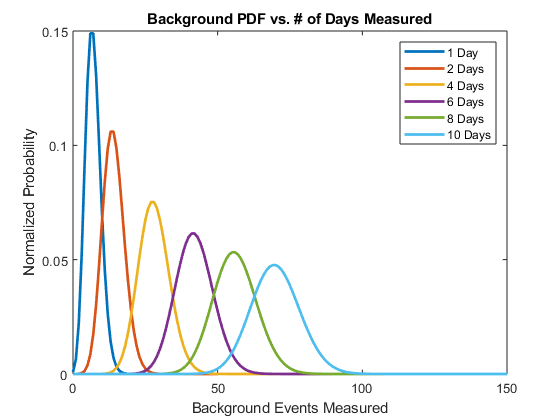

background = 7; 
gammaray = 11; 

distribution = makedist('Poisson','lambda',background); 

x = 0:1:25; 

pdf1 = pdf(distribution,x); 
pdf2 = conv(pdf1,pdf1); 
pdf4 = conv(pdf2,pdf2); 
pdf6 = conv(pdf2,pdf4); 
pdf8 = conv(pdf4,pdf4); 
pdf10 = conv(pdf8,pdf2); 

x1 = 0:1:length(pdf1)-1; 
x2 = 0:1:length(pdf2)-1; 
x4 = 0:1:length(pdf4)-1; 
x6 = 0:1:length(pdf6)-1; 
x8 = 0:1:length(pdf8)-1; 
x10 = 0:1:length(pdf10)-1; 

figure(1)
plot(x,pdf1,'LineWidth',2); 
hold on 
plot(x2,pdf2,'LineWidth',2); 
plot(x4,pdf4,'LineWidth',2);
plot(x6,pdf6,'LineWidth',2); 
plot(x8,pdf8,'LineWidth',2);
plot(x10,pdf10,'LineWidth',2); 
hold off
title('Background PDF vs. # of Days Measured'); 
xlabel('Background Events Measured'); 
ylabel('Normalized Probability'); 
xlim([0 150]); 
legend('1 Day','2 Days','4 Days','6 Days','8 Days','10 Days'); 

Since this is a normalized probability distribution, the area under each of the graphs is equal to 1. The most likely number of events measured for each of these distributions is the peak of each plot. We can see that for the 10-day sum, the most likely number of events observed is ~70, and for the 1-day sum the most likely number of measurements is 7. This indicates, as we would expect, that integrating over more days yields a most likely measurement that is simply the 1-day average multiplied by the number of days measured. But notice that each of the plots tends to spread out more, which we will discuss soon. 

Now we seek to show that the distribution remains a Poisson distribution after being summed for over 5 days, and try and explain mathematically and conceptually why we expect this to be the case. 

To do so, we take our convolved 10-day distribution and construct a brand new Poisson distribution with an average background measurement equivalent to that of our selected 10-day distribution. If the separate plots match, then we will have demonstrated that the convolved 10-day distribution has in fact remained as a Poisson distribution. 

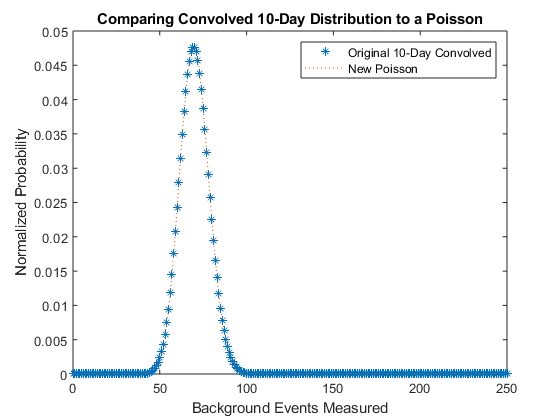

x = 0:1:length(pdf10)-1; 
lambda = dot(pdf10,x); 

figure(2)
pdf10Poisson = makedist('Poisson','lambda',lambda); 
plot(0:length(pdf10)-1,pdf10,'*'); 
hold on
plot(0:length(pdf10)-1,pdf(pdf10Poisson,0:length(pdf10)-1),':'); 
xlabel('Background Events Measured'); 
ylabel('Normalized Probability'); 
title('Comparing Convolved 10-Day Distribution to a Poisson'); 
legend('Original 10-Day Convolved','New Poisson'); 

As we can see, the two distributions align perfectly. Since the Poisson distribution gives data on the number of events happening within a single day (or any arbitrary period), it makes sense that convolving (which we know to be equivalent to adding) multiple such Poisson distributions should just yield a final probability density function that has a total number of events equivalent to the 1-day number of events * the total number of days measured. We see that this proportional scaling (simply because we are adding) has caused the resultant graphs to be identical. 

Now, we take the total number of events within a measurement period and divide it by the total number of days measured, hence giving a probability distribution that evolves as we *average *days. We divide the measured background events for each convolved distribution by the number of days in each respective distribution, as follows:

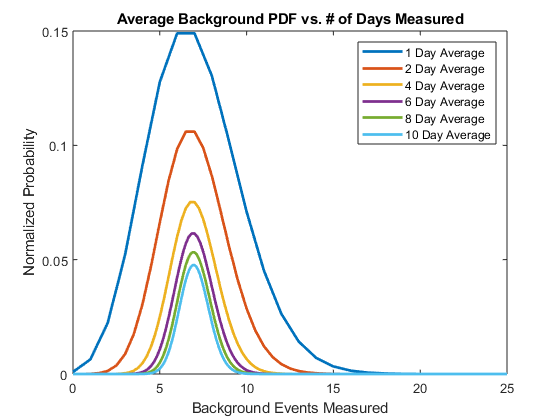

figure(3)
plot(x1/1,pdf1,'LineWidth',2);
hold on 
plot(x2/2,pdf2,'LineWidth',2);
plot(x4/4,pdf4,'LineWidth',2);
plot(x6/6,pdf6,'LineWidth',2);
plot(x8/8,pdf8,'LineWidth',2);
plot(x10/10,pdf10,'LineWidth',2);
hold off
xlabel('Background Events Measured'); 
ylabel('Normalized Probability'); 
title('Average Background PDF vs. # of Days Measured'); 
legend('1 Day Average','2 Day Average','4 Day Average','6 Day Average','8 Day Average','10 Day Average'); 

As we can see, graphing the *average *for each of the convolved distributions keeps them as Poisson distributions, but increasing the number of days causes each distribution to become more Gaussian in shape. Note that the most likely number of events for each distribution is still 7, which matches our specified 1-day cosmic background average. The central limit theorem in statistics dictates that the addition of independent random variables in some situations will tend towards a normal, or Gaussian distribution. We see proof in this plot, as the convolved distributions for progressively more days adopt a stronger bell-shape and have less flaring out of their tails. 

Now assume that we measured for 17 days, and observed a total of 17 * 11 = 187 (gamma-ray average) events from a source over this period, compared to the expected 17 * 7 = 119 events measured from the background. We wish to calculate the significance of this observation to determine whether it was a relevant observation that stands out against the background noise or whether it can accounted for simply by random fluctuation. 

testPeriod = 17; 
events = testPeriod*gammaray; 

    % From the results of 1b, we know that the lambda parameter for this
    % 17-day data collection distribution should just be 17*lambda for a
    % single day's data = 17*7 = 119
    
pdf17dist = makedist('Poisson','lambda',119); 
probs = cdf(pdf17dist,events,'upper'); 
sigma = norminv(probs); 
disp(abs(sigma))

    5.8017



With a sigma of only 3.9, we determine that this is not in fact a significant observation, even it seems relatively far (187 vs. 119) from the background radiation. 

PROBLEM 2 

We now repeat some of the same methodology as in the above problem, except this time for a skewed distribution, such as the Rayleigh distribution. We first explore how this distribution changes as we *average* over more observing intervals. 

We create a Rayleigh distribution with a "b" parameter of 5. 

x = 0:100; 
ray1 = makedist('Rayleigh','b',5); 
ray1 = pdf(ray1,x);
ray2 = conv(ray1,ray1); 
ray4 = conv(ray2,ray2); 

Now we convolve the initial 1-day distribution to get observation intervals for the following number of days: 5, 10, 25, 50, 100, 200. 

ray5 = conv(ray4,ray1); 
ray10 = conv(ray5,ray5); 
ray20 = conv(ray10,ray10); 
ray25 = conv(ray20,ray5); 
ray50 = conv(ray25,ray25); 
ray100 = conv(ray50,ray50); 
ray200 = conv(ray100,ray100); 

We now plot each of the above convolved distributions in addition to the 1-day distribution to show how the Rayleigh distribution *for the average number of events each day* changes as it the total observation period is taken to be larger and larger. 

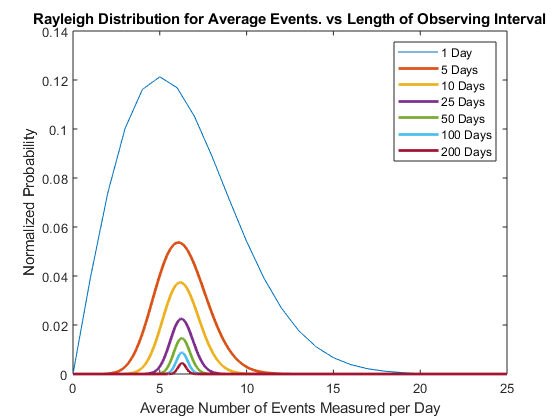

figure(4)
plot(x,ray1); 
x5 = 0:length(ray5)-1; 
x10 = 0:length(ray10)-1; 
x25 = 0:length(ray25)-1; 
x50 = 0:length(ray50)-1; 
x100 = 0:length(ray100)-1; 
x200 = 0:length(ray200)-1; 
hold on 
plot(x5/5,ray5,'LineWidth',2);
plot(x10/10,ray10,'LineWidth',2);
plot(x25/25,ray25,'LineWidth',2);
plot(x50/50,ray50,'LineWidth',2);
plot(x100/100,ray100,'LineWidth',2);
plot(x200/200,ray200,'LineWidth',2);
hold off
xlabel('Average Number of Events Measured per Day'); 
ylabel('Normalized Probability'); 
title('Rayleigh Distribution for Average Events. vs Length of Observing Interval'); 
legend('1 Day','5 Days','10 Days','25 Days','50 Days','100 Days','200 Days'); 
xlim([0 25]); 

Remember that since each distribution is normalized, the area under each plot is equivalent to 1. That means that even though the 1-day distribution looks the largest, the tails of it rapidly drop off after a measurement of 20 on the x-axis, beyond the point where they would actually add anything to the probability integral. Looking at the 200-day distribution, we see that although the average # of events seems to have an extremely small probability, the tails of the distribution extend well beyond the limits of the graph (well beyond 250 on the x-axis) and therefore there is a large amount of the integral that is just difficult to see. 

We also notice that quite rapidly, each of the convolved Rayleigh distributions has centered in around a mean, and is looking progressively more Gaussian. By graphing these same distributions on a logarithmic distribution for the y-axis probability, we can examine their Gaussian nature. Plots that are much more parabolic are more Gaussian, which we see below. 

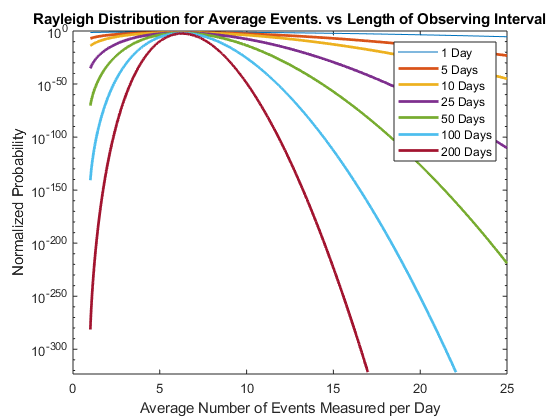

figure(5)
plot(x,ray1); 
hold on 
plot(x5/5,ray5,'LineWidth',2);
plot(x10/10,ray10,'LineWidth',2);
plot(x25/25,ray25,'LineWidth',2);
plot(x50/50,ray50,'LineWidth',2);
plot(x100/100,ray100,'LineWidth',2);
plot(x200/200,ray200,'LineWidth',2);
hold off
xlabel('Average Number of Events Measured per Day'); 
ylabel('Normalized Probability'); 
title('Rayleigh Distribution for Average Events. vs Length of Observing Interval'); 
legend('1 Day','5 Days','10 Days','25 Days','50 Days','100 Days','200 Days'); 
xlim([0 25]); 
set(gca,'YScale','log'); 

It is clear from this logarithmically scaled graph that increasing the size of the convolved Rayleigh distribution makes it progressively more Gaussian in nature. Indeed, the longest-convolved distribution over 200 days is the most Gaussian of the entire lot. 

PROBLEM 3 

For this problem, assume now that we have a signal-free background *Gaussian *distribution (per pixel) with a mean of 0 and a constant width. By looking at all the pixels on our detector, we are able to measure an area equivalent to the width of the Gaussian background times the number of pixels in question. Assume that during this observation we measure a certain signal. How can we tell whether or not this signal is a significant one? 

As we have done previously, the answer to above simply lies in finding the sigma for the measurement. As a quick recap - recall what a Gaussian probability density function looks like, and the fact that the integral between any two regions on this graph (or for any probability density function) yields the probability of measuring something in that interval. So say we integrate from an interval of 5 out to positive infinity - we are effectively calculating the probability that a signal of 5 or larger will ever be measured in our data distribution. And for each of these integrated probabilities, there is an associated 'sigma' that describes how far out the measurement in question is, and this sigma is directly related to the area under the calculated integral. 

For a measurement to be considered extremely significant and worthy of discovery, it must be 5-sigma or higher. This means that 99.99994% of the graph falls before the actual measurement, or that the probability of measuring something higher than this value is only 0.00006%. When we think about this as comparing our measured signal to the background distribution, we are saying that there is only a 0.00006% change that our measurement was actually just a random fluctuation and was caused by the background. 

Hence, the 5-sigma value serves as a strong indicator that a measurement is indeed significant and may indicate a discovery. 

For this problem, we construct and plot a Gaussian of mean 0 and a width of 3. Say we measure a signal of strength 11.7. Taking into account what we just discussed, what is the significance of this detection? Is it indicative of a discovery? 

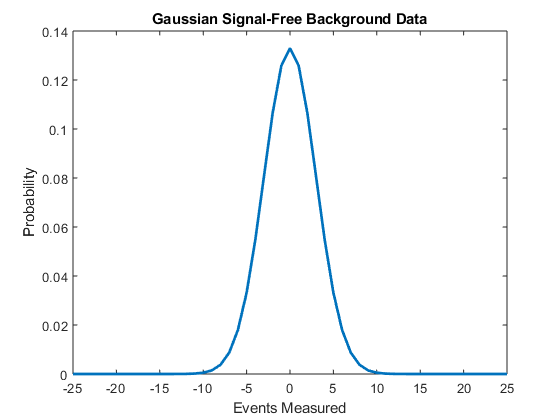

x = -100:1:100; 
swift = makedist('Norma','mu',0,'sigma',3); 
swift1 = pdf(swift,x); 
signal = 11.7; 
figure(7)
plot(x,swift1,'LineWidth',2); 
xlabel('Events Measured'); 
ylabel('Probability'); 
title('Gaussian Signal-Free Background Data'); 
xlim([-25 25]); 

The significance and sigma of the discovery is: 

  % Now calculating the significance and sigma of the discovery 
    
prob = cdf(swift,signal,'upper'); 
sigma = norminv(prob); 
disp(abs(sigma))

    3.9000



Our sigma is only 3.9, and therefore does not meet the 5-sigma threshold to be considered significant enough to qualify as a discovery. 

Now assume that we collected data from not 1, but 10,000 pixels. How can we depict the probability distribution of this background? By taking the data from 10,000 pixels, and if we assume each pixel is identical with the same individual background noise, we are effectively multiplying the background data by a factor of 10,000. In other words, we are convolving the initial Gaussian distribution 10,000 times to produce a new one. As a result, any fluctuation in the background data has been effectively amplified by this same factor of 10,000 - this suggests that for a measurement to be considered significant, it must be *even stronger* to stand out against the signal flux from the background. 

If we wanted to calculate the significance of the previous 11.7 measurement amongst this set of 10,000 pixels, all we need to do is scale the previously found probability by 10,000 and recalculate the sigma for this statistic.     

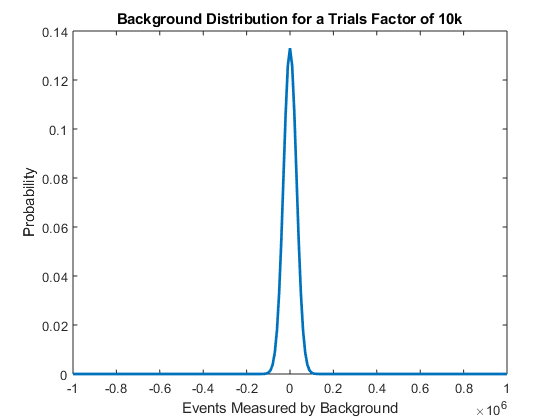

figure(8)
plot(x*10000,swift1,'LineWidth',2); 
xlabel('Events Measured by Background'); 
ylabel('Probability'); 
title('Background Distribution for a Trials Factor of 10k'); 

prob10k = prob*10000; 
sigma10k = norminv(prob10k); 
disp(abs(sigma10k))

    0.0477



Now, our sigma is only 0.0477, which is not significant at all, and can easily be explained by background flux. This makes sense from a conceptual point of view, since there are now 10,000 times as many sources of signal noise, and it is far easier for this noise to add together and produce signals that would be significant for just a single pixel. 

PROBLEM 4 

Our exploration in the previous problem with 10,000 pixels and scaling the noise 10,000 times was dealing with something called the *trials *factor. Taking data from more sources amplifies the possibility of finding a discovery, but it also amplifies any background noise in our signals. The balance between these two amplifications causes the sensitivity of a search to drop as the trials factor is increased, and this sensitivity is what we explore in this problem. 

Using the same Gaussian as in problem 3, we seek to find the signal required for a 5-sigma detection if we are collecting data from only 1 pixel - i.e a trials factor of 1. 

sig_VI = normcdf(5,'upper'); 
prob_VI = icdf(swift,1-sig_VI); 
disp(prob_VI)

   15.0000



We must measure a signal of at least 15 to be considered significant when looking at the data from a single pixel. 

Now if we have 10,000 pixels, the minimum signal required to be significant becomes: 

sig_VII = sig_VI/10000; 
prob_VII = icdf(swift,1-sig_VII); 
disp(prob_VII)

   19.6516



    
ratio = prob_VII/prob_VI; 
disp(ratio)

    1.3101



As we can see, the minimum signal for the 10,000 pixels collection is now 19.6516, which reflects the fact that our signal must overcome the increased noise from the larger sample size of pixels. The ratio of the threshhold for the trials factor of 1:10000, however, is only 1:1.31, suggesting that the signal sensitivity is not nearly proportional to the trials factor. This makes sense - the tails of both distributions drop off rapidly once they are more than 2 or 3 widths from the mean of the Gaussian distribution. This means that the probability under the graph in each of these regions is already extremely small. As a result, it is not necessary to move as far out on the x-axis for the 10k trials-scaled distribution as we would think, since there isn't a huge amount of area that actually needs to be compensated for. In other words, the integral we must perform from the signal out to infinity does not grow along the x-axis too much. 

If we change our trials factor by three orders of magnitude, the new signal to be considered significant must now be: 

sig_VX = sig_VI/10000000; 
prob_VX = icdf(swift,1-sig_VX); 
disp(prob_VX)

   22.5424



Even now, with a trials factor of 10,000,000, the signal required to be considered significant is only ~3 points higher than the 10,000 trials factor significant signal, with a signal ratio of 1:1.1473 for a trials ratio of 1:1000. Looking at the trends above indicates that increasing the trials factor has a diminishing effect on the sensitivity threshold, meaning that each successive order of magnitude increase for the trials factor necessitates a smaller and smaller increase in the minimum signal required to be considered significant. 

EXTRA CREDIT: 

From the results above, we see that increasing the trials factor of an experiment has diminishing returns on the sensitivity threshold required for a signal to be considered significant. Increasing the trials factor from 1 to 1,000 will incur a larger sensitivty penalty than increasing from 1,000 to 1,000,000. As we mentioned, this is due to the fact that the above probability density functions have negligible area in their integrals once we cross more than a few widths away from the mean. As a result, the next integral that must be performed from the observed signal out to infinity must be conducted over a smaller region, since there simply isn't as much area to make up for. Thus, we can infer from this that the shape of the distribution - primarily how quickly it drops off as we move away from the mean, is the major factor in determining the sensitivity penalty for a trials factor. Distributions with a much larger portion of their pdf near the mean will have smaller penalities, while distributions that are far more spread out and drop off less at the tails will incur a larger sensitivity penalty. 